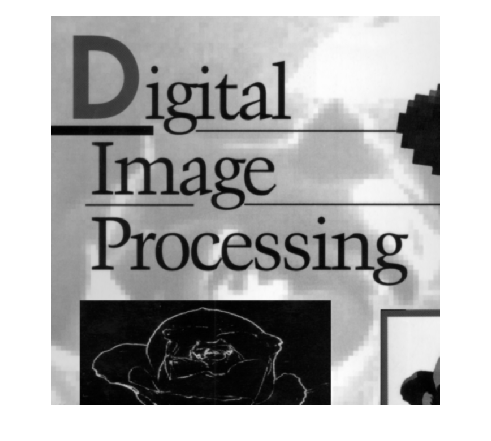

bild =imread("book-cover.tif");
imshow(bild)

max(max(bild))

ans = uint8
253

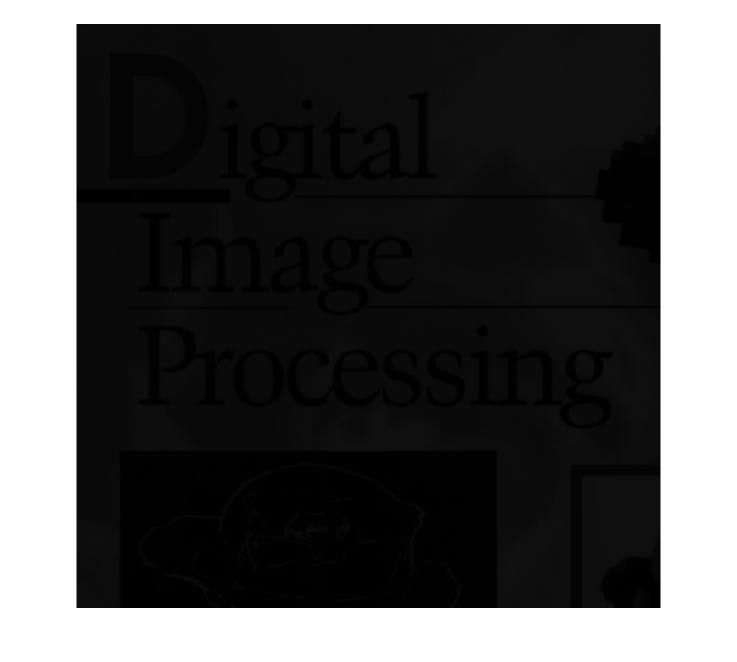


bild2 = bild/16;
imshow(bild2)

max(max(bild2))

ans = uint8
16


bild3 = bild2*16

bild3 = 688×688 uint8 matrix
   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   160   160   160   160   176   176   176
   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   160   160   176   176   176   160   160   160   176   176   176
   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176
   176   176   176   176   176   176   160   160   176   176   176  

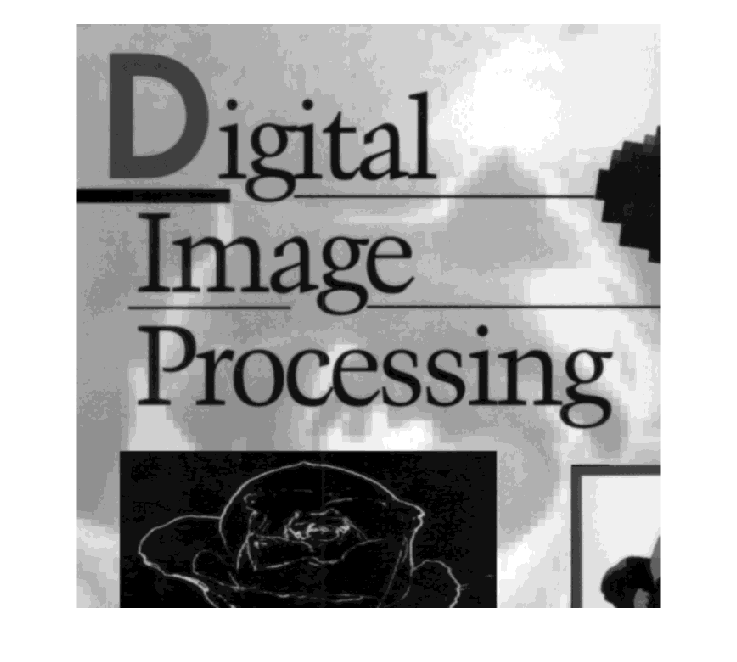

imshow(bild3)

unique(bild3)

ans = 17×1 uint8 column vector
     0
    16
    32
    48
    64
    80
    96
   112
   128
   144


image = im2double(imread("einstein-low-contrast.tif"));
unique(image)

ans =     0.2902
    0.2941
    0.2980
    0.3020
    0.3059
    0.3098
    0.3137
    0.3176
    0.3216
    0.3255


min(min(image))

ans = 0.2902

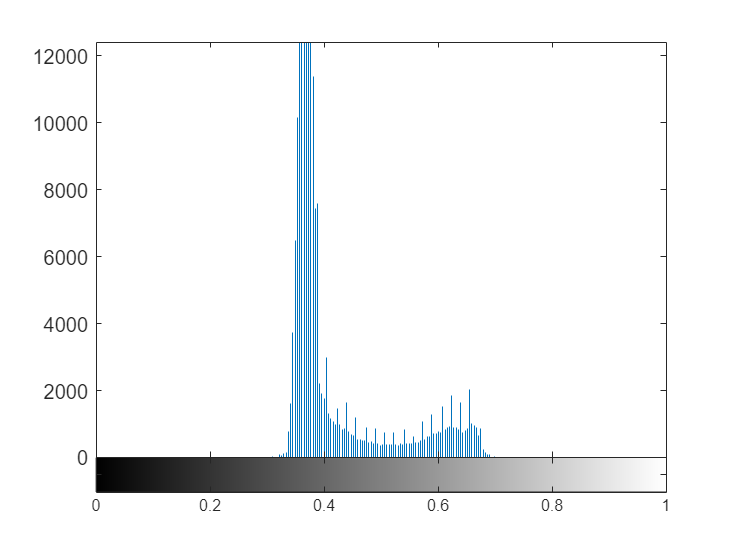


imhist(image)

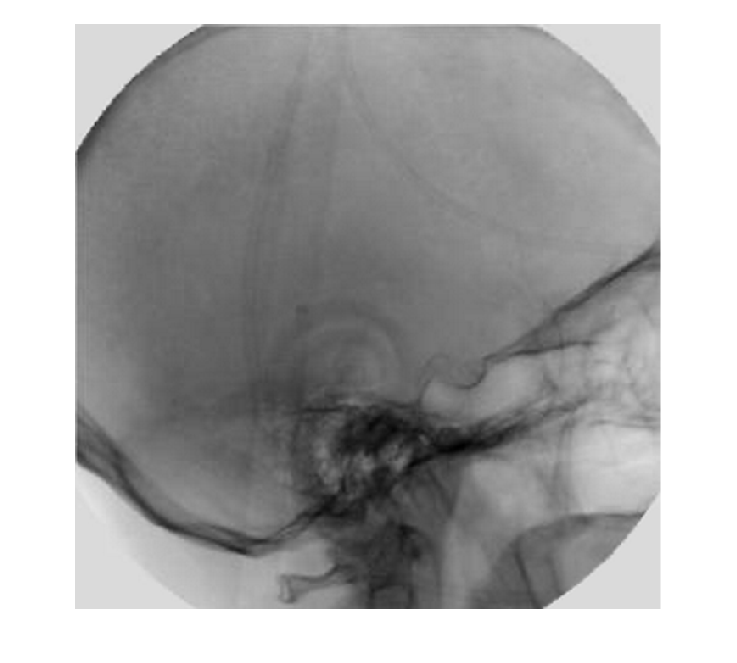

image2 = im2double(imread('angiography-mask-image.tif'));
image3 = im2double(imread('angiography-live-image.tif'));

imshow(image2)

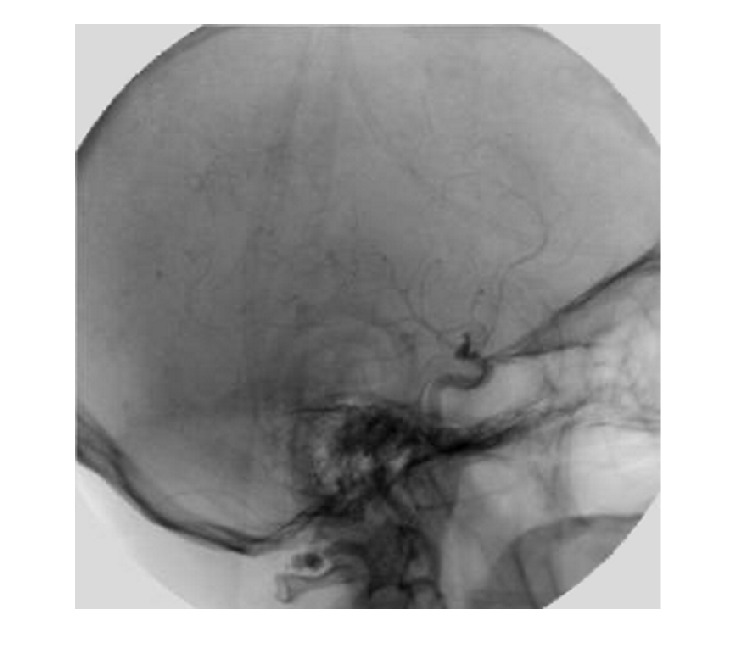

imshow(image3)

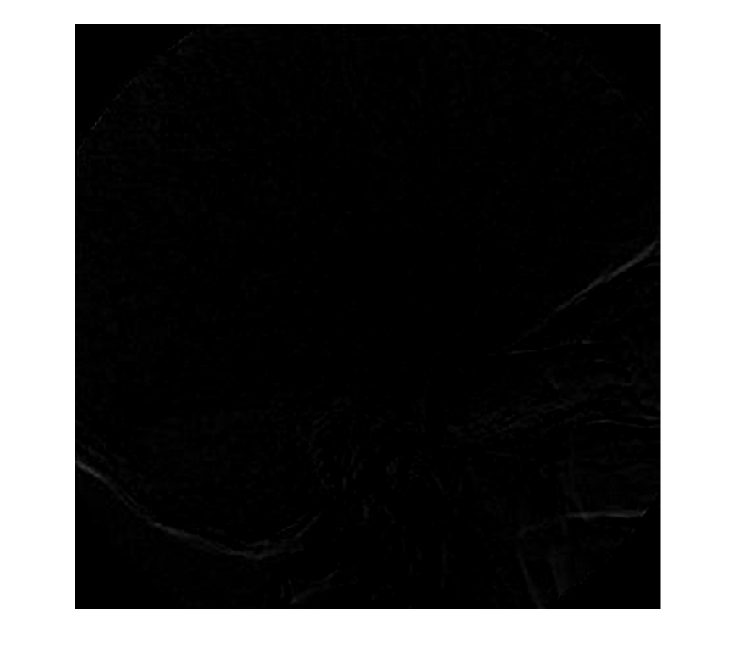



for i = 1:690
    for j = 1:690
image4(i,j)= image3(i,j)-image2(i,j);

    end
end

mindub = min(min(image4));
maxdub = max(max(image4));

for i = 1:690
    for j = 1:690
        image5(i,j) = ((image4(i,j)-mindub)/(maxdub-mindub)); 
    end
end

imshow(image4)

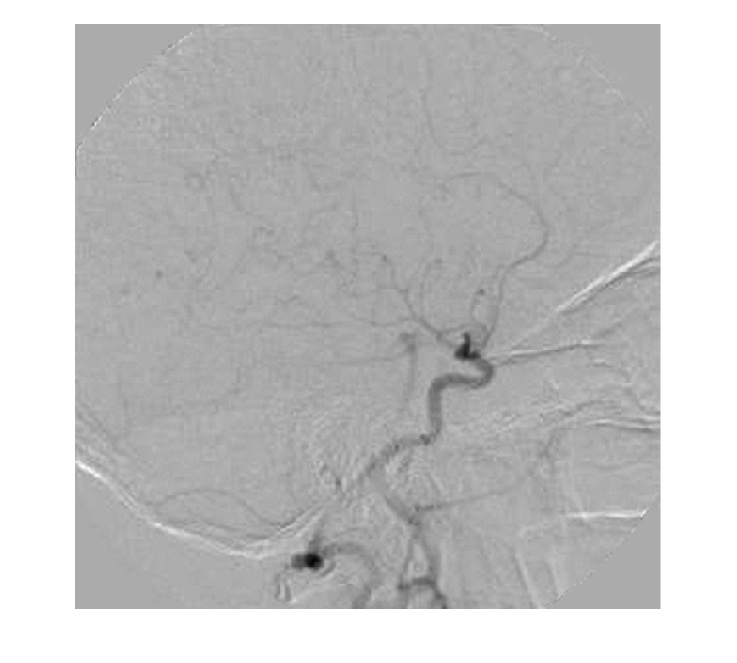

imshow(image5)

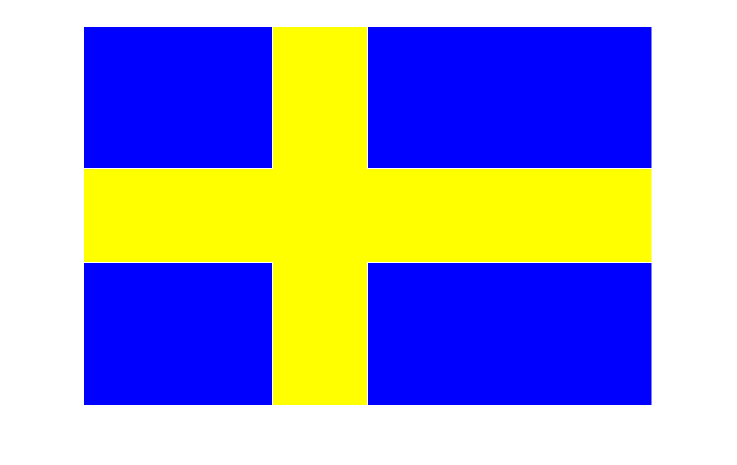

I = zeros(400,600,3);

I(150:250,1:600,1)=1; 
I(1:400,200:300,1)=1;

I(150:250,1:600,2)=1; 
I(1:400,200:300,2)=1;

I(1:150,1:200,3)=1; 
I(1:150,300:600,3)=1; 

I(250:400,1:200,3)=1;
I(250:400,300:600,3)=1;
imshow(I)

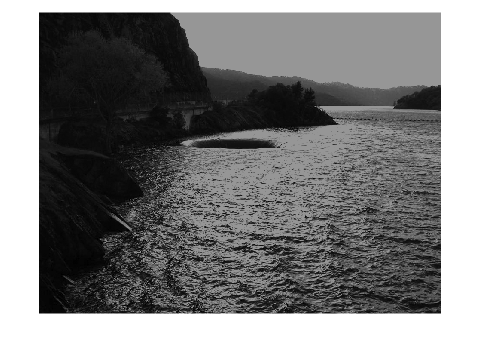

test = imread("spillway-dark.tif");
imshow(test)

test1 = GammaCorrection(test,0.5,0,1);

lowgv = 0

uppgv = 0.5882

GImage =     0.2309    0.2160    0.2160    0.2000    0.2160    0.2449    0.2449    0.2582    0.2582    0.2449    0.2582    0.2708    0.2582    0.2449    0.2582    0.2582    0.2160    0.2449    0.2582    0.2708    0.2449    0.2309    0.2582    0.2828    0.2944    0.2828    0.2449    0.2309    0.2309    0.2309    0.2449    0.2449    0.2309    0.2309    0.2449    0.2309    0.2309    0.2160    0.1826    0.1826    0.2449    0.2449    0.2449    0.2449    0.2449    0.2582    0.2708    0.2828    0.2944    0.2828
    0.2708    0.2449    0.2160    0.2160    0.2160    0.2309    0.2449    0.2582    0.2582    0.2582    0.2582    0.2582    0.2708    0.2582    0.2582    0.2582    0.2160    0.2449    0.2708    0.2708    0.2449    0.2309    0.2582    0.2828    0.3055    0.2944    0.2708    0.2582    0.2449    0.2309    0.2449    0.2449    0.2309    0.2309    0.2309    0.2309    0.2309    0.2309    0.2160    0.2000    0.2160    0.2309    0.2309    0.2449    0.2449    0.2708    0.2944    0.3162    0.2944

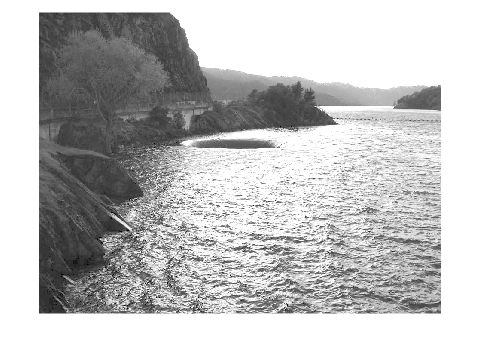

imshow(test1)

rgbflower = imread("RGBflower.tif")

rgbflower = 509×656×3 uint8 array
rgbflower(:,:,1) =

   174   175   176   174   177   177   177   179   179   177   179   180   179   178   177   177   176   176   177   177   177   178   176   177   176   177   175   175   173   173   174   176   176   177   177   177   177   177   175   177   178   178   179   180   180   180   179   177   179   180   182   182   177   165   159   171   173   173   174   174   173   170   169   171   168   171   174   174   173   171   172   172   171   174   173   174   173   173   171   170   172   173   168   163   171   180   177   170   158   153   154   155   155   159   159   162   165   167   169   172   175   172   171   177   180   182   184   186   184   184   184   184   185   186   187   184   188   190   185   183   186   188   187   184   188   188   187   189   192   188   188   192   190   184   180   186   192   192   191   188   188   187   187   190   193   194   195   197   196   195   195   195   198   197   196   196   197   1

irflower = imread("IRflower.tif")

irflower = 509×656 uint16 matrix
   21724   21470   21470   21724   21982   21982   21724   21470   21724   21982   21982   21982   21724   21470   21724   21982   21982   21982   21470   21470   21724   21982   21982   21982   21724   21470   21470   21724   21724   21724   21470   21724   21982   21724   21470   21470   21724   21724   21470   21470   21470   21724   21724   21470   21470   21470   21470   21724   21982   21982
   21724   21724   21724   21982   21982   21724   21470   21470   21724   21982   21982   21982   21724   21724   21724   21982   21982   21724   21470   21724   21982   21982   21982   21724   21724   21724   21724   21724   21724   21724   21470   21724   21724   21470   21470   21470   21724   21982   21724   21470   21470   21724   21982   21724   21724   21470   21470   21724   21982   21982
   21982   21982   21982   22240   21982   21724   21724   21982   21982   21982   21724   21724   21982   21982   21982   21724   21724   21724   21724   21724   21

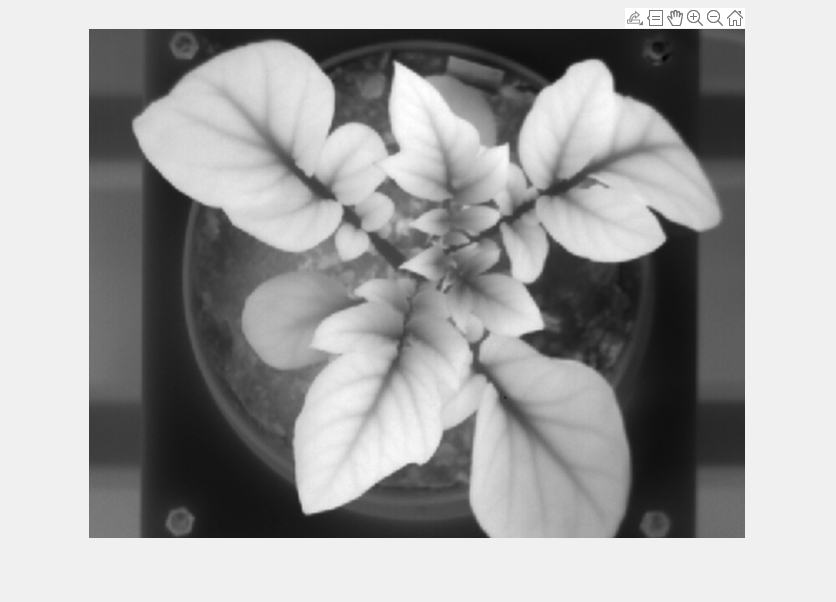

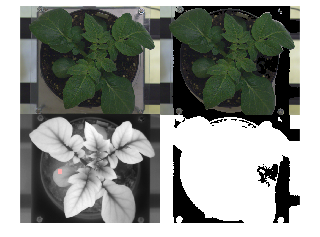

test2 = test2(:,:,1) =

    0.6824    0.6863    0.6902    0.6824    0.6941    0.6941    0.6941    0.7020    0.7020    0.6941    0.7020    0.7059    0.7020    0.6980    0.6941    0.6941    0.6902    0.6902    0.6941    0.6941    0.6941    0.6980    0.6902    0.6941    0.6902    0.6941    0.6863    0.6863    0.6784    0.6784    0.6824    0.6902    0.6902    0.6941    0.6941    0.6941    0.6941    0.6941    0.6863    0.6941    0.6980    0.6980    0.7020    0.7059    0.7059    0.7059    0.7020    0.6941    0.7020    0.7059    0.7137    0.7137    0.6941    0.6471    0.6235    0.6706    0.6784    0.6784    0.6824    0.6824    0.6784    0.6667    0.6627    0.6706    0.6588    0.6706    0.6824    0.6824    0.6784    0.6706    0.6745    0.6745    0.6706    0.6824    0.6784    0.6824    0.6784    0.6784    0.6706         0         0         0    0.6588    0.6392    0.6706    0.7059    0.6941    0.6667    0.6196    0.6000    0.6039    0.6078    0.6078    0.6235    0.6235    0.6353    0.6471    0.

test2 = LevelSlicing(rgbflower,irflower,1)